# Project 2 (Autonomous Cart Speed Profile)

%{
Quadratic + numerical change
   originally from ES115 Engineering Computer Applications, Module 1
   Project Bank, project 3
Author: Tori Testa
Version: 1.0
Date: 2026-04-02
Purpose:
   -to model the speed of a cart in motion
Input:
   -
Output:
   -speed and acceleration plots
   - 
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   - 
%}

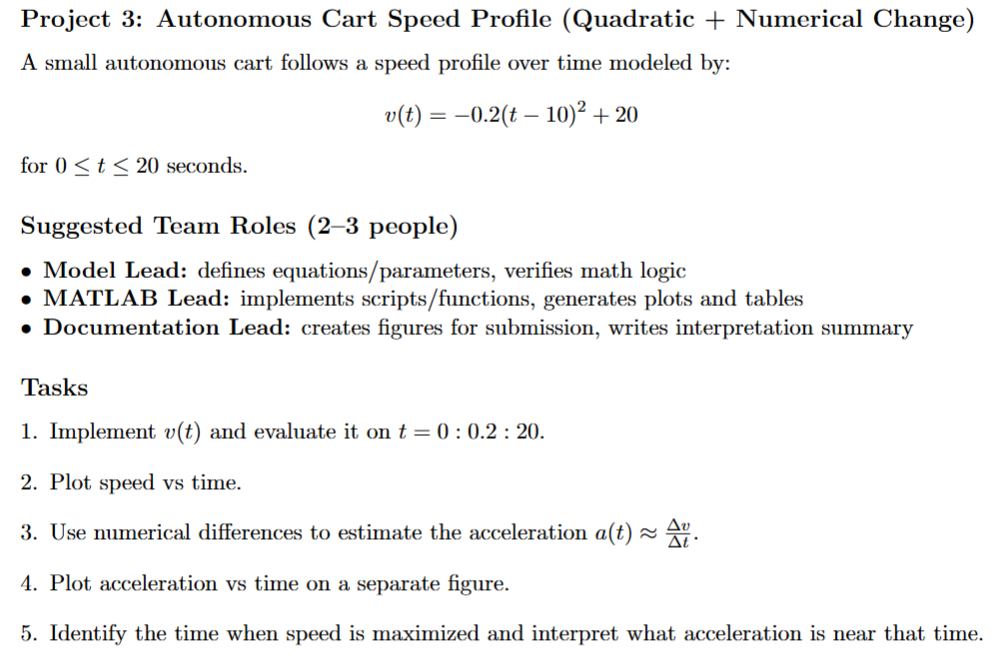

t = 0:0.2:20 % defines t on a specific interval

t =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


v = -0.2*((t-10).^2) + 20 % defines the velocity of the cart

v =          0    0.7920    1.5680    2.3280    3.0720    3.8000    4.5120    5.2080    5.8880    6.5520    7.2000    7.8320    8.4480    9.0480    9.6320   10.2000   10.7520   11.2880   11.8080   12.3120   12.8000   13.2720   13.7280   14.1680   14.5920   15.0000   15.3920   15.7680   16.1280   16.4720   16.8000   17.1120   17.4080   17.6880   17.9520   18.2000   18.4320   18.6480   18.8480   19.0320   19.2000   19.3520   19.4880   19.6080   19.7120   19.8000   19.8720   19.9280   19.9680   19.9920


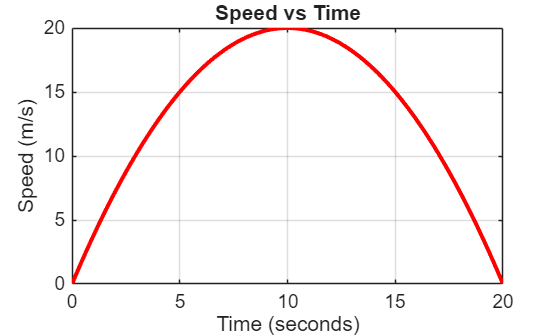

% plot speed vs time
plot(t, v, 'r-', 'linewidth', 2) % makes the line red and have a width of 2
title('Speed vs Time')  % creates a title for the graph
xlabel('Time (seconds)') % labels the x axis as time
ylabel('Speed (m/s)')  % labels the y axis as the speed of the cart
grid on  % turns the grid lines on

%estimate acceleration using numerical differences
dt = 0.2; % defines dt 
a = diff(v) / dt  % defines acceleration as the derivative of velocity with respect to time

a =     3.9600    3.8800    3.8000    3.7200    3.6400    3.5600    3.4800    3.4000    3.3200    3.2400    3.1600    3.0800    3.0000    2.9200    2.8400    2.7600    2.6800    2.6000    2.5200    2.4400    2.3600    2.2800    2.2000    2.1200    2.0400    1.9600    1.8800    1.8000    1.7200    1.6400    1.5600    1.4800    1.4000    1.3200    1.2400    1.1600    1.0800    1.0000    0.9200    0.8400    0.7600    0.6800    0.6000    0.5200    0.4400    0.3600    0.2800    0.2000    0.1200    0.0400


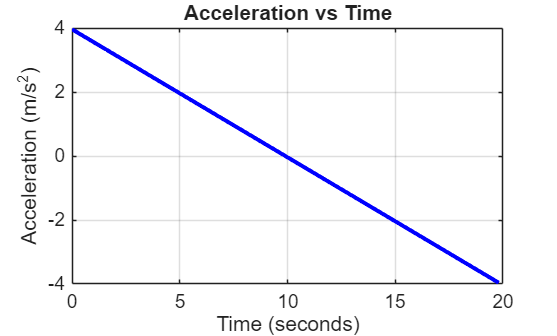

% plots acceleration vs time
t_a = t(1:end-1); % a has one less value than t, this makes it for only these values of t, allowing for a vs t to be graphed
plot(t_a, a, 'b-', 'LineWidth',2)  % makes the line blue with a width of 2
title('Acceleration vs Time')  % creates a title for the graph
xlabel('Time (seconds)')  % labels the x axis as time
ylabel('Acceleration (m/s^2)') % labels the y axis as acceleration
grid on % turns on the grid lines

%identify when speed is maximized and what t is for that time
[vMax, idx] = max (v); % finds the maximum of v
tMax = t(idx); % this
% Displays the maximum speed and the corresponding time
fprintf('Maximum speed: %.2f m/s at time: %.2f seconds\n', vMax, tMax); %displays the max speed and when it occurs

Maximum speed: 20.00 m/s at time: 10.00 seconds


function [start] = userEntry() % creates a user entry function
start = input('Enter a time, in seconds, between 0 and 20: ');  % prompts the user to enter a time
if start < 0 && start > 20  
    start = 10;     % if the time entered by the user is negative or greater than 20, 10 seconds will be used as the time
end
end

UTime = userEntry(); % defines UTime as the value entered by the user

vExact = -0.2*(UTime - 10)^2 + 20; % finds the velocity at the user entered time
aExact = -0.4*(UTime - 10);  % finds the acceleration at the user entered time

fprintf('Speed at %g seconds is %g m/s\n', UTime, vExact); % displays the speed at the user entered time

Speed at 3 seconds is 10.2 m/s


fprintf('Acceleration at %g seconds, is %g m/s^2\n', UTime, aExact);  % displays the acceleration at the user entered time

Acceleration at 3 seconds, is 2.8 m/s^2
